# Filter a Signal using Coefficient Vectors

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

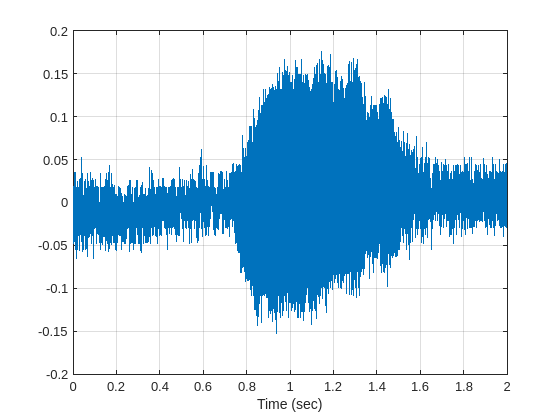

[whaley, fs] = audioread("./data/whalesound.wav");
t = (0:numel(whaley)-1)'/fs;
plot(t, whaley)
grid on
xlabel("Time (sec)")

biir = [0.5 0.25];
aiir = [1 -0.1];
bfir = [0.2 0.5 0.2];

## Task 1

whaleiir = filter(biir, aiir, whaley);

## Task 2

whalefir = filter(bfir, 1, whaley);

## Task 3

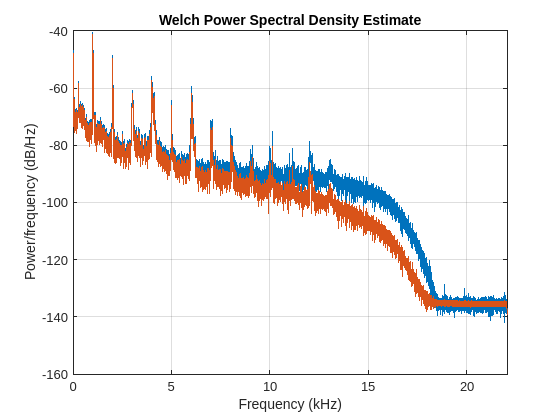

pwelch([whaley whalefir], [], [], [], fs)